# Performance of various versions of "The Five Loops"

You will want to activate the plotting of a new performance curve by changing "( 0 )" to "( 1 )" in the appropriate place.

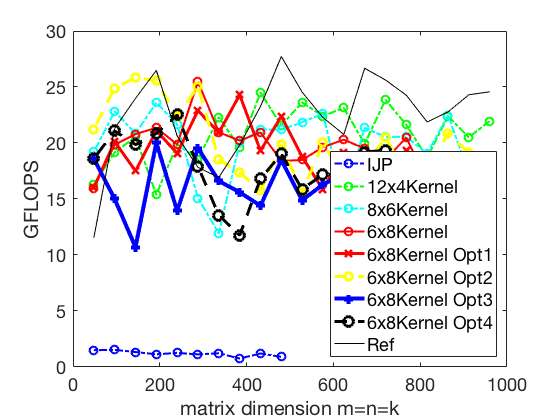

plot_colors = [ 0 0 0; 0 0 1; 0 1 0; 0 1 1; 1 0 0; 1 0 1; 1 1 0; 1 1 1];

% Create figure
figure1 = figure('Name','GFLOPS');

% Create axes, labels, legends.  In future routines for plotting performance, 
% the next few lines will be hidden in the script.
axes2 = axes('Parent',figure1);
hold(axes2,'on');
ylabel( 'GFLOPS', 'FontName', 'Helvetica Neue' );
xlabel( 'matrix dimension m=n=k', 'FontName', 'Helvetica Neue' );
box(axes2,'on');
set( axes2, 'FontName', 'Helvetica Neue', 'FontSize', 18);

% Plot performance data for JI_4x4Kernel
if ( 1 )
  system( 'cp ../../../Week1/C/data/output_IJP.m .' );
  output_IJP   % load data
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', 'IJP', 'MarkerSize', 8, 'LineWidth', 2, ...
      'Marker', 'o', 'LineStyle', '-.', 'Color', plot_colors( 2,: ) );
end

% Plot performance data for Five_Loops_Pack_12x4Kernel
if ( 1 )
  output_Five_Loops_Pack_12x4Kernel   % load data
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', '12x4Kernel', 'MarkerSize', 8, 'LineWidth', 2, ...
      'Marker', 'o', 'LineStyle', '-.', 'Color', plot_colors( 3,: ) );
end

% Plot time data for Five_Loops_Pack_8x6Kernel (to plot change "0" to "1")
if ( 1 ) 
  output_Five_Loops_Pack_8x6Kernel
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', '8x6Kernel', 'MarkerSize', 8, 'LineWidth', 2, ...
        'Marker', 'o', 'LineStyle', '-.', 'Color', plot_colors( 4,: ) );
end

% Plot time data for Five_Loops_Pack_6x8Kernel  (to plot change "0" to "1")
if ( 1 ) 
  output_Five_Loops_Pack_6x8Kernel
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', '6x8Kernel', 'MarkerSize', 8, 'LineWidth', 2, ...
        'Marker', 'o', 'LineStyle', '-', 'Color', plot_colors( 5,: ) );
end

% Plot time data for Five_Loops_Pack_6x8Kernel_Opt1 (to plot change "0" to "1")
if ( 1 ) 
  output_Five_Loops_Pack_6x8Kernel_Opt1
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', '6x8Kernel Opt1', 'MarkerSize', 8, 'LineWidth', 3, ...
        'Marker', 'x', 'LineStyle', '-', 'Color', plot_colors( 5,: ) );
end

% Plot time data for Five_Loops_Pack_6x8Kernel_Opt2  (to plot change "0" to "1")
if ( 1 ) 
  output_Five_Loops_Pack_6x8Kernel_Opt2
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', '6x8Kernel Opt2', 'MarkerSize', 8, 'LineWidth', 3, ...
        'Marker', 'o', 'LineStyle', '--', 'Color', plot_colors( 7,: ) );
end

% Plot time data for Five_Loops_Pack_6x8Kernel_Opt3  (to plot change "0" to "1")
if ( 1 ) 
  output_Five_Loops_Pack_6x8Kernel_Opt3
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', '6x8Kernel Opt3', 'MarkerSize', 8, 'LineWidth', 4, ...
        'Marker', '+', 'LineStyle', '-', 'Color', plot_colors( 2,: ) );
end

% Plot time data for Five_Loops_Pack_6x8Kernel_Opt4  (to plot change "0" to "1")
if ( 1 ) 
  output_Five_Loops_Pack_6x8Kernel_Opt4
  assert( max(abs(data(:,6))) < 1.0e-10, ...
      'Hmmm, better check if there is an accuracy problem');
  plot( data(:,1), data(:,5), 'DisplayName', '6x8Kernel Opt4', 'MarkerSize', 10, 'LineWidth', 3, ...
        'Marker', 'o', 'LineStyle', '--', 'Color', plot_colors( 1,: ) );
end


% Optionally show the reference implementation performance data
if ( 1 )
  plot( data(:,1), data(:,3), 'MarkerSize', 8, 'LineWidth', 1, ...
        'LineStyle', '-', 'DisplayName', 'Ref', 'Color', plot_colors( 1,: ) );
end

% Adjust the x-axis and y-axis range to start at 0
v = axis;                   % extract the current ranges
axis( [ 0 v(2) 0 v(4) ] )   % start the x axis and y axis at zero

% Optionally change the top of the graph to capture the theoretical peak
if ( 0 )
    turbo_clock_rate = 2.6;
    flops_per_cycle = 16;
    peak_gflops = turbo_clock_rate * flops_per_cycle;

    axis( [ 0 v(2) 0 peak_gflops ] )  
end

legend2 = legend( axes2, 'show' );
set( legend2, 'Location', 'southeast', 'FontSize', 18) ;


% Uncomment if you want to create a pdf for the graph
% print( 'Plot_Blocked_MMM.pdf', '-dpdf' );